# Robotics 2 - Final exam - June 11, 2018

## Exercise 1

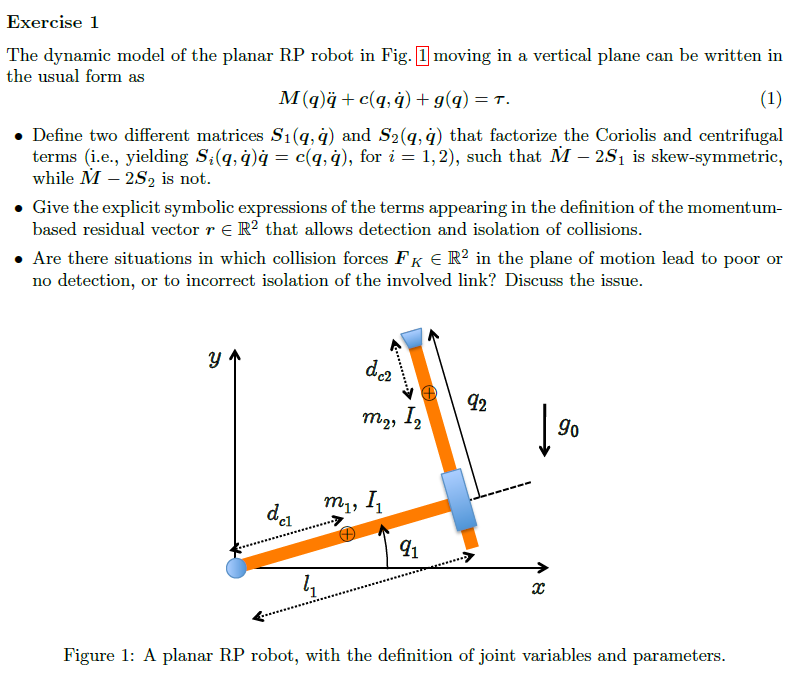

% % This part is isolated from previous sectionclear;clc
% clear all, close all, clc;
% % syms k q1(t) q2(t) q3(t)
% sigmaD = [0,1];
% n = length(sigmaD);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% %
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,-g0,0]';

s

% R2Robot=['rp';'xy';sigmaD]
% z = Gen_param(n);
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% 
% z.g=g;
% 
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1%2=with DH table
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% % z.opt_expr={[l(1)+q(2)],[q(2)]};
% % z.rcdefined=true;
% z.prismatic_CoM_method(2)=2;

% 
% 
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

% Pc
% M

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)

## gravity computation

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, g, isMotor)
% U{:}

% g_q

## get dinamyc paramters

% % [Msubs, dynamicParameters, aM] = getDynamicParameters(M,q,[])
% % [Gsubs, dynamicParametersG, aG] = getDynamicParameters(g_q,q,[g0],1)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)

% [C,cac,Csubs,S1] = getCs(M,q,q_dot)
% % u =simplify( M*q_ddot + cac+g_q+F_v*q_dot)
% % [usubs, dynamicParametersu, au] = getDynamicParameters(u,q,[])
% %
% % Msubs = All(:,1:n)
% % gSubs = diag(All(:,n+1:2*n))
% % FSubs = All(:,2*n+1:end)
% [Md,Mtd,qt]  = getM_dot2(M, q, q_dot)

% [S0,S_] = getGenericS0(q,q_dot)
% S_(:,1)
% S0{1}
% % S0_=subs(S0{2},S_(:,1)',[q_dot(2),0]);
% S0_=subs(S0{1},S_(:,2)',[-z.m(2)*z.q_dot(1)*(z.dc(2)-z.q(2)),0]);
% S0_
% S2=S1+S0_
% S1
% Md
% simplify(Md-2*S1)
% simplify(Md-2*S2)

% % u_subs = Msubs*q_ddot + gSubs +FSubs*q_dot

**Collisions**

defining collisions link 1

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',1,'F_pos',rho(1)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 

Defining collisions link 2

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',2,'F_pos',rho(1)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% 
% 

## when the forces over link 2 won't be detected or missdetected?

% %
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*[cos(q(1)),sin(q(1)),0]' ,'joint',2,'F_pos',rho(2)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout] = getCollisions(z)

% zout.g_q
% zout.S
% zout.J_c_collisions_{:}
% zout.vc_collisions
% zout.Vc_T_dot_Fk
% zout.Tau_c
% zout.r
% zout.p_r
% zout.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% zout.Pc_collisions

% 
% % collide1=
% rho=sym('rho',[2,1],'real')
% F_0=sym('F_0','real')
% z.collides=[struct('F',F_0*zout.Pc_collisions ,'joint',2,'F_pos',rho(2)),
% %             struct('F',[0,-1,0]' ,'joint',1,'F_pos',l(1)),
% %             struct('F',[0, 1,0]' ,'joint',2,'F_pos',l(2)/2)
%             ];
% z.collides(1)

computing colissions

% z.prismatic_CoM_method=[1,2]
% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans,zout2] = getCollisions(z)

% zout2.g_q
% zout2.S
% zout2.J_c_collisions_{:}
% zout2.vc_collisions
% zout2.Vc_T_dot_Fk
% zout2.Tau_c
% zout2.r
% zout2.p_r
% zout2.to_integrate
% % vc_=subs(vc,q,q_)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);

## Exercise 2

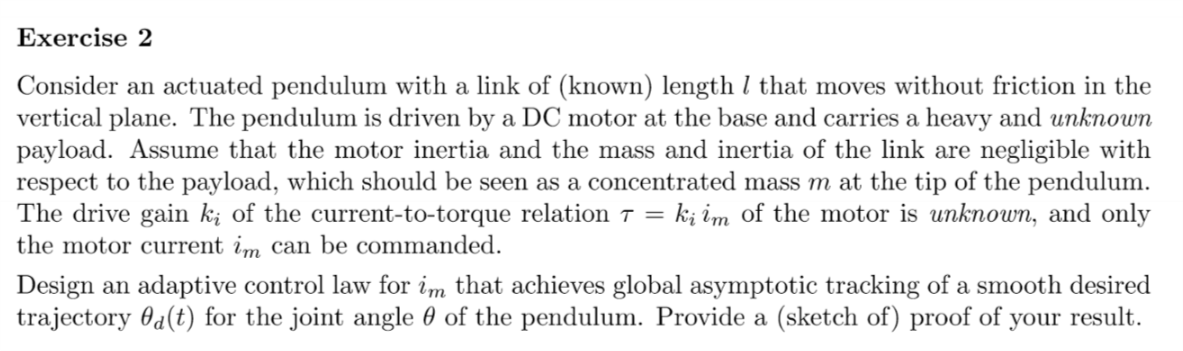

% clear;clc
% %
% % % syms k q1(t) q2(t) q3(t)
% sigma = [0];
% n = length(sigma);
% % t = sym('t', 'real');
% % q = sym('q_', [n 1],'real');
% % q_dot = sym('q_dot_', [n 1],'real');
% % q_ddot = sym('q_ddot_', [n 1],'real');
% 
% q = sym('theta_', [n 1],'real');
% q_dot = sym('theta_dot_', [n 1],'real');
% q_ddot = sym('theta_ddot_', [n 1],'real');
% 
% %
% dc = sym('dc_', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l_', [n 1],'real');
% m = sym('m_', [n 1],'real');
% I = sym('I_', [n 1],'real');
% 
% % motor definitions
% % q_m = sym('q_m_', [n 1],'real');
% % q_dot_m = sym('q_dot_m_', [n 1],'real');
% % q_ddot_m = sym('q_ddot_m_', [n 1],'real');
% 
% q_m = sym('theta_m_', [n 1],'real');
% q_dot_m = sym('theta_dot_m_', [n 1],'real');
% q_ddot_m = sym('theta_ddot_m_', [n 1],'real');
% 
% %desired values
% 
% % q_d = sym('q_d_', [n 1],'real');
% % q_dot_d = sym('q_dot_d_', [n 1],'real');
% % q_ddot_d = sym('q_ddot_d_', [n 1],'real');
% 
% q_d = sym('theta_d_', [n 1],'real');
% q_dot_d = sym('theta_dot_d_', [n 1],'real');
% q_ddot_d = sym('theta_ddot_d_', [n 1],'real');
% 
% 
% %
% % dc = sym('dc_', [n 1],'real');
% 
% % l = sym('l_', [n 1],'real');
% m_m = sym('m_m_', [n 1],'real');
% I_m = sym('I_m_', [n 1],'real');
% 
% 
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% g=[0,g0,0]';

defining z struct

% R2Robot=['r';'y';sigma]
% z = Gen_param(n);
% z.vartoderivate='theta';
% 
% z.g0=g0;
% z.g=g;
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot=q_ddot;
% z.m=m;
% z.I=I;
% 
% z.q_m=q_m;
% z.q_dot_m=q_dot_m;
% z.q_ddot_m=q_ddot_m;
% z.m_m=m_m;
% z.I_m=I_m;
% 
% z.q_d=q_d;
% z.q_dot_d=q_dot_d;
% 
% z.dc=dc;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[];
% % z.movingframes=[];
% z.angle_=sym(zeros(1,n));
% l_0=sym('l','real')
% % z.opt_expr={l,[l_0,l_0,l_0,l_0]'};%not necessary
% 
% % z.rcdefined=true;
% 
% z.ismotor=false;%% important!!!!
% z.motoronly=false;
% z.vartoderivate="theta";

## axis offset

% %
% % h=sym('h','real')
% % %x,y,z
% % z.xyx_offset=sym(zeros(3,n));
% % z.xyx_offset(:,1)=[0,h,0]'%

% % %Global q reference?
% % % clear
% % % z.q_global
% % z.global_q_reference=true
% % if(z.global_q_reference)
% %     [z.q_global,z.q_dot_global]=convert_local2global_q(z.q,z.q_dot,z.sigmaD)
% % end

% 
% 
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% pendulum = pendulum_model(z)

% pendulum.M
% pendulum.M_dot%it should be computed using the k_i value but in this case the inertia matrix is equal to zero
% pendulum.T
% pendulum.U{1}
% pendulum.tau
% 
% pendulum.tau_subs
% pendulum.dynamicParameterstau
% pendulum.atau

Viscouz terms

% % F_v=sym('F_v',[n,1],'real').*eye(n)
% % [All, dynamicParamsReturn, a]= getDynamicParameters([pendulum.M,diag(pendulum.g_q)],q,[q_dot.',g0],2)
% 

## parametrization in terms of current im

% z.i_m=sym('i_m','real');
% z.tau_sym=sym('tau','real');
% z.k_i=sym('k_i','real');
% z.i_m_=z.tau_sym/z.k_i;
% 
% z.i_m_

## adaptative control

% Y=sym('Y','real')
% % Y_=getLinearParametrization(u_subs,a)
% Y_=pendulum.tau_subs
% dynamicParameters_i_m=pendulum.dynamicParameterstau/z.k_i
% a=pendulum.atau

## Adpative control law

% z_u.vartoderivate="theta";
% z_u.M=pendulum.M/z.k_i;%it is only possible in this case because isonly 1 link, a pendulum
% z_u.M_dot=pendulum.M_dot/z.k_i;
% z_u.Y=Y;
% z_u.Y_=Y_;
% z_u.q=q;
% z_u.q_d=q_d%q desired
% z_u.q_dot_d=q_dot_d;
% t=sym('t','real');
% q_dots=derivate_D(q_d,n,t,'theta_d');
% z_u.q_d_dot =q_dots.dot;
% z_u.q_d_ddot=q_dots.ddot;
% z_u.a=a;
% z_u.n=n;
% z_u.q_dot=q_dot;
% z_u.q_ddot=q_ddot;
% 
% u_control=Adpatative_Control_Law(z_u)
% u_control.Y_r_
% u_control.u
% u_control.u_
% u_control.a_hat_dot
% u_control.a_hat_dot_
% u_control.mq_r_dot %I'm not sure about this
% u_control.q_r_dot_
% 
% display("lyapunov and LaSalle")
% u_control.a_tilde_dot
% u_control.a_tilde_dot_
% 
% u_control.mV
% u_control.V_
% u_control.V_def2_
% 
% u_control.mV_dot
% 
% u_control.V_dot_
% u_control.V_dot_def2_


## Version 2


% This part is isolated from previous sectionclear;clc
clear all, close all, clc;
% syms k q1(t) q2(t) q3(t)
sigmaD = [0];
n = length(sigmaD);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
%
dc = sym('dc', [n 1],'real');
% dc(6)=dc(6)
% k = sym('k', [n 1],'real');
l = sym('l', [n 1],'real');
m = sym('m', [n 1],'real');
m_p = sym('m_p','real');
%m(2)=m(2)+m_p
I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
g0 = sym('g0','real');
g=[0,g0,0]';

R2Robot=['r';'y';sigmaD]

R2Robot = 3×1 char array
    'r'
    'y'
    ' '


z = Gen_param(n);
z.sigmaD=R2Robot;
% l(1)=0 %don't do this because dc1 is going to dissaperar
z.opt_expr={[I(1)],[0]};%use this instead
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.q_ddot=q_ddot;

z.g=g;

z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1%2=with DH table, 1 normal mode

z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: 1
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_reference:

% z.dhTable=dhTable
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));

% z.rcdefined=true;
z.prismatic_CoM_method(2)=2;
z.xyonly=true

z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_refere

% q = sym('q', [n,1],'real');
% qd= sym('qd', [n,1],'real');
% a = sym('a', [n,1],'real');
% d = sym('d', [n,1],'real');

% % z.dhTable = [pi/2    , 0     , z.l(1) , q(1);
% %             0       , z.l(2)  , 0   , q(2);]

% % 
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE2(z)
[Pc,vc,w,T,Ti,M,VarShortRobot,Trans]=getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×1 char]
                       l: [1×1 sym]
                      l_: []
                       q: [1×1 sym]
                   q_dot: [1×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [1×1 sym]
                       m: [1×1 sym]
                       I: [1×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 1
                  angle_: [1×1 sym]
               rcdefined: 1
                opt_expr: {[1×1 sym]  [0]}
                collides: []
                joint_on: 1
                  xyonly: 1
    prismatic_CoM_method: [1 2]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: [3×1 sym]
            task_defined: {}
              xyx_offset: []
      global_q_refere

si falla aquí está el error


$$a = l_{1}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\mathrm{dc}}_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$To\_derive = \left(\begin{array}{c} -l_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ -l_{1}\,\sin\left(q_{1}\left(t\right)\right)\\ 0 \end{array}\right)$$

$$q\_t = q_{1}\left(t\right)$$

z_derivated = struct with fields:
    dot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]


z_derivated = struct with fields:
     dot_t: [3×1 sym]
    ddot_t: [3×1 sym]
    tdot_t: [3×1 sym]


z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×1 sym]
       ddot_t: [3×1 sym]
       tdot_t: [3×1 sym]
          dot: [3×1 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×1 sym]
        ddot_t: [3×1 sym]
        tdot_t: [3×1 sym]
           dot: [3×1 sym]
     dot_short: []
          ddot: [3×1 sym]
    ddot_short: []
          tdot: [3×1 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$vc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right)\\ -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

$$w = \left(\begin{array}{c} 0\\ 0\\ {\dot{q}}_{1} \end{array}\right)$$

$$T = \frac{{{\mathrm{dc}}_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$Ti = \frac{{{\mathrm{dc}}_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

$$M = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

VarShortRobot = struct with fields:
    Pc: [3×1 sym]
    vc: [3×1 sym]
     w: [3×1 sym]
     T: [1×1 sym]
    Ti: [1×1 sym]
     M: [1×1 sym]


Trans = struct with fields:
                 TTotal: [4×4 sym]
                PTotali: [3×1 sym]
               TPartial: {[4×4 sym]}
                 RTotal: [3×3 sym]
               RPartial: {[3×3 sym]}
                 PTotal: [3×1 sym]
        Jacobian_PTotal: [3×1 sym]
    Jacobian_dot_PTotal: [3×1 sym]
               PPartial: {[3×1 sym]}
                     Pc: [3×1 sym]
                RTotali: {[3×3 sym]}
           ThetaPartial: [1×1 sym]
             ThetaTotal: [1×1 sym]
                     vc: [3×1 sym]
                      w: [3×1 sym]
                      T: [1×1 sym]
                     Ti: [1×1 sym]
                      M: [1×1 sym]


Ti(1)

$$ans = \frac{{{\mathrm{dc}}_{1}}^{2}\,m_{1}\,{{\dot{q}}_{1}}^{2}}{2}$$

Pc

$$Pc = \left(\begin{array}{c} -{\mathrm{dc}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

M

$$M = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

% M(1,1)
% M(1,2)
% M(1,3)
% M(2,2)
% M(2,3)
% M(3,3)

[Msubs, dynamicParameters, aM] = getDynamicParameters2(M,z.q,[])

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$Msubs = a_{1}$$

$$dynamicParameters = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

$$aM = a_{1}$$

% %[m1*dc1^2 + m2*dc2^2 + m3*dc3^2 + I1 + I2 + I3; m3*dc3^2 + I3; m2 + m3; dc3*m3; 2*dc2*m2]


% known_params=[z.m(3),z.dc(3),z.I(3)]'%z.m(3)*z.dc(3)^2 + z.I(3),z.m(3),z.m(3)*z.dc(3)]'
known_params=[z.l,g0]'

$$known\_params = \left(\begin{array}{c} l_{1}\\ g_{0} \end{array}\right)$$

% [Msubs2, dynamicParameters2, aM2]=adaptative_control_get_paramateres2(M,dynamicParameters,aM,known_params,[])

[struct_sub_mat,params]=Adpatative_Control_parameters(Msubs,dynamicParameters,known_params,aM)

$$submats = a_{1}$$

$$a\_k\_sym = \left(\begin{array}{c} a_{\mathrm{k1}}\\ a_{\mathrm{k2}} \end{array}\right)$$

a_k_sym_zeros =      0
     0


B_u =      2
     2


I_u =      1
     2


$$new\_a = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

$$partial\_a = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

$$partial\_a = {{\mathrm{dc}}_{1}}^{2}\,m_{1}$$

$$a\_u\_sym = a_{\mathrm{u1}}$$

a_u_sym_zeros = 0

B = 8

I = 1

$$new\_a2 = a_{\mathrm{u1}}$$

B_a = 4

I_a = 1

struct_sub_mat = struct with fields:
    new_submats: [1×1 sym]


params = struct with fields:
    known_parameters_: [2×1 sym]


params = struct with fields:
    known_parameters_: [2×1 sym]
     known_parameters: [2×1 sym]


params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]


params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]


params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]
     unknown_parameters: [1×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [1×1 sym]
    new_submats_u: [1×1 sym]


struct_sub_mat = struct with fields:
      new_submats: [1×1 sym]
    new_submats_u: [1×1 sym]
    new_submats_k: [1×1 sym]


struct_sub_mat = struct with fields:
       new_submats: [1×1 sym]
     new_submats_u: [1×1 sym]
     new_submats_k: [1×1 sym]
    new_submats_u_: [1×1 sym]


struct_sub_mat = struct with fields:
       new_submats: [1×1 sym]
     new_submats_u: [1×1 sym]
     new_submats_k: [1×1 sym]
    new_submats_u_: [1×1 sym]
    new_submats_k_: [1×1 sym]


struct_sub_mat = struct with fields:
       new_submats: [1×1 sym]
     new_submats_u: [1×1 sym]
     new_submats_k: [1×1 sym]
    new_submats_u_: [1×1 sym]
    new_submats_k_: [1×1 sym]


params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]
     unknown_parameters: [1×1 sym]


% 

% struct_sub_mat.new_submats_u
% params.unknown_parameters
% params.unknown_parameters_

isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, z.l, z.m, z.dc, z.g, isMotor)

*** Computation of Potential Energy (Jacobian-based method) 


$$qall\_sincos\_comb = \left(\begin{array}{cc} \sin\left(q_{1}\right) & \cos\left(q_{1}\right) \end{array}\right)$$

$$PE = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

$$PE\_short = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

$$g\_q\_short = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$g\_q = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$PE = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

U = 1×1 cell array
    {1×1 sym}


$$g\_q\_short = {\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$

$$PE\_short = -{\mathrm{dc}}_{1}\,g_{0}\,m_{1}\,\cos\left(q_{1}\right)$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×1 cell array
    {1×1 sym}


$$cac = 0$$

Csubs = 1×1 cell array
    {1×1 sym}


$$S = 0$$

cac

$$cac = 0$$

S

$$S = 0$$

% g_q
% U{:}

% % F_v=sym('F',[2,1],'real')
ki_inv=sym('k_i_inv','real')%inverted it 

$$ki\_inv = k_{i,\mathrm{inv}}$$

% [All, dynamicParamsReturn, a]= getDynamicParameters([M,diag(g_q),F_v],q,[q_dot.',g0],2)
[All, dynamicParamsReturn, aM]= getDynamicParameters2([M,diag(g_q)]*ki_inv,q,[z.q_dot,g0,z.dc]',2)

$$none\_sym\_value = {\mathrm{zxw}}_{\mathrm{none},\mathrm{David}}$$

>> Getting dynamic coefficients. Might take a while...
MSubs second iteration (before re-replacement)
si falla uncomment this line verify  una lineas arriba


$$All = \left(\begin{array}{cc} a_{1}\,{{\mathrm{dc}}_{1}}^{2} & a_{1}\,{\mathrm{dc}}_{1}\,g_{0}\,\sin\left(q_{1}\right) \end{array}\right)$$

$$dynamicParamsReturn = k_{i,\mathrm{inv}}\,m_{1}$$

$$aM = a_{1}$$

% [All, dynamicParamsReturn, aM]= getDynamicParameters([M,S],q,[],2)

All

$$All = \left(\begin{array}{cc} a_{1}\,{{\mathrm{dc}}_{1}}^{2} & a_{1}\,{\mathrm{dc}}_{1}\,g_{0}\,\sin\left(q_{1}\right) \end{array}\right)$$

% S_subs=simplify(expand(All(:,4:end)))

## Computing adaptative parameters

% known_params=[z.dc]'
% [struct_sub_mat,params]=Adpatative_Control_parameters(All,dynamicParamsReturn,known_params,aM)
struct_sub_mat.new_submats_u=All

struct_sub_mat = struct with fields:
       new_submats: [1×1 sym]
     new_submats_u: [1×2 sym]
     new_submats_k: [1×1 sym]
    new_submats_u_: [1×1 sym]
    new_submats_k_: [1×1 sym]


params.unknown_parameters=aM

params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]
     unknown_parameters: [1×1 sym]


params.unknown_parameters_=dynamicParamsReturn

params = struct with fields:
      known_parameters_: [2×1 sym]
       known_parameters: [2×1 sym]
    unknown_parameters_: [1×1 sym]
     unknown_parameters: [1×1 sym]


% struct_sub_mat.new_submats_u
% struct_sub_mat.new_submats_k
% params.known_parameters
% params.known_parameters_
% params.unknown_parameters
% params.unknown_parameters_

## linear paramatrization for unkown terms

% % %complete model
a_order_u = params.unknown_parameters

$$a\_order\_u = a_{1}$$

Msubs_u = struct_sub_mat.new_submats_u(:,1)

$$Msubs\_u = a_{1}\,{{\mathrm{dc}}_{1}}^{2}$$

gsubs_u = struct_sub_mat.new_submats_u(:,2)

$$gsubs\_u = a_{1}\,{\mathrm{dc}}_{1}\,g_{0}\,\sin\left(q_{1}\right)$$

% gSubs = diag(All(:,7:9))
% FSubs = All(:,10:12)

torqueSubs_u = Msubs_u*z.q_ddot + gsubs_u %+ gSubs +FSubs*qd

$$torqueSubs\_u = a_{1}\,{\ddot{q}}_{1}\,{{\mathrm{dc}}_{1}}^{2}+a_{1}\,g_{0}\,\sin\left(q_{1}\right)\,{\mathrm{dc}}_{1}$$

[Y_u, Yshort_u]=getLinearParametrization(torqueSubs_u,a_order_u)

$$Y\_u = {\ddot{q}}_{1}\,{{\mathrm{dc}}_{1}}^{2}+g_{0}\,\sin\left(q_{1}\right)\,{\mathrm{dc}}_{1}$$

$$Yshort\_u = {\ddot{q}}_{1}\,{{\mathrm{dc}}_{1}}^{2}+g_{0}\,s_{1}\,{\mathrm{dc}}_{1}$$

Y_u

$$Y\_u = {\ddot{q}}_{1}\,{{\mathrm{dc}}_{1}}^{2}+g_{0}\,\sin\left(q_{1}\right)\,{\mathrm{dc}}_{1}$$

## linear paramatrization for kown terms

% % % %complete model
% a_order_k = params.known_parameters
% % params.known_parameters_([1,3,2])

% Msubs_k = struct_sub_mat.new_submats_k(:,1)
% % Ssubs_k = struct_sub_mat.new_submats_k(:,2)
% gSubs_k = diag(struct_sub_mat.new_submats_k(:,2))
% % FSubs = All(:,10:12)

% torqueSubs_k = Msubs_k*z.q_ddot + Ssubs_k*z.q_dot %+ gSubs +FSubs*qd

% [Y_k, Yshort_k]=getLinearParametrization(torqueSubs_k,a_order_k)

% Y_k

## Defining control law

% q_r=sym('q_r_',[n,1],'real')
% q_r_dot=sym('q_r_dot_',[n,1],'real')
% q_r_ddot=sym('q_r_ddot_',[n,1],'real')
% M_law=Msubs_u+Msubs_k
% S_law=Ssubs_u+Ssubs_k
% torqueSubs_r = Msubs_u*q_r_ddot+ Ssubs_u*q_r_ddot%+ gSubs +FSubs*qd

## Linearizing

% [Y_r, Yshort_r]=getLinearParametrization(torqueSubs_r,a_order_u)

% Y_r

 